# View Augmented Images

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

rng(123)
anmlPath = "../data/Animals/";
anmlds = imageDatastore(anmlPath, "IncludeSubfolders", true)

anmlds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\01ad3ff1d94eb557.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\0346463867a297f4.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\038fae9e70c4c3f1.jpg'
                               ... and 439 more
                              }
                     Folders: {
                              ' ...\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\Animals'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


## Task 1

An image datastore named `flwrds` has been created. It contains five images of flowers.

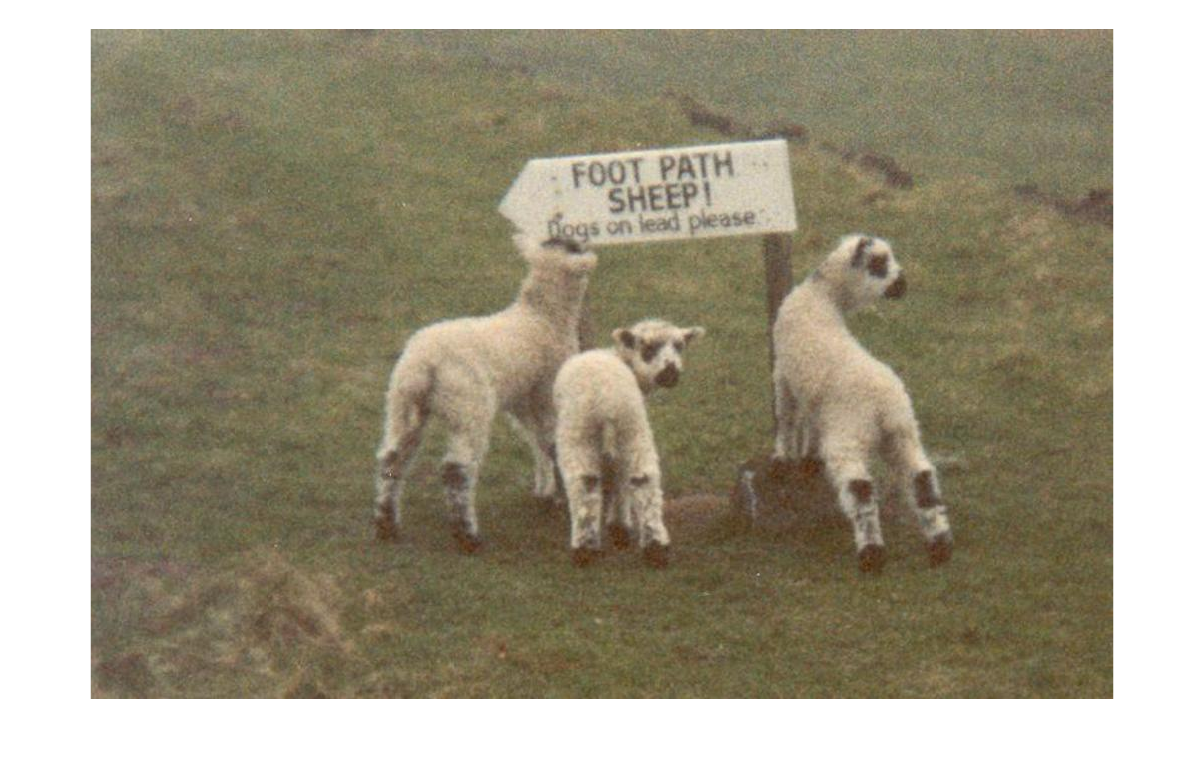

imshow(read(anmlds))

## Task 2

The `imageDataAugmenter` function can be used to choose your augmentation. Possible augmentations include transformations like reflection, translation, and scaling.

Generally, you should choose an augmentation that is relevant to your data set. In this activity, you will rotate the images a random amount.

`imageDataAugmenter``(``"RandRotation"``,``[``min` `max``])`

aug = imageDataAugmenter("RandRotation", [0, 360]);

## Task 3

When you create an augmented image datastore, you need to specify the output image size, the source of the files, and the augmenter.

`augmentedImageDatastore``(``size``,``ds``,``...`

`"DataAugmentation"``,``augmenter``)`

augImds = augmentedImageDatastore([200 200], anmlds, "DataAugmentation", aug);

## Task 4

You can read data from an augmented datastore with the `read` function. Instead of returning one image, `read` will return a batch of data. Each returned image has a different random augmentation.

data = read(augImds);

## Task 5

To display a transformed image, you need to extract one of the images from the table. The variable containing the images is named `input`.

`im` `=` `data``.input``{``n``}`

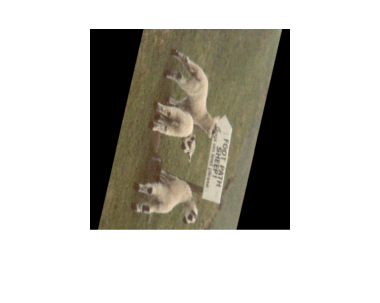

im = data.input{1};
imshow(im);